## Feature manipulation Experiment 0 

In this notebook we will see the behaviour of features from the two instances obtained in "Exp1_RHHjustification". From that behaviour we will try to design by hand a HH able to properly solve such instances. 

%First let's clean everything and add needed folders
clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities

First let's load the Instances from Exp1_RHHjustification 

load("Exp1_I1.mat")
load("Exp1_I2.mat")
%For precaution let's reset the instances 
I2.reset
I1.reset

Let's remember how are the makespans when solving with LPT and SPT

%Loading LPT and SPT
load("SPT.mat")
load("LPT.mat")

%Solving instances with LPT and saving the value 
I1_Solved_LPT=LPT.solveInstanceSet({I1});
I2_Solved_LPT=LPT.solveInstanceSet({I2});

%Solving instances with SPT and saving the value 
I1_Solved_SPT=SPT.solveInstanceSet({I1});
I2_Solved_SPT=SPT.solveInstanceSet({I2});

makespans{1,2}='I1';
makespans{1,3}='I2';
makespans{2,1}='LPT';
makespans{3,1}='SPT';
makespans{2,2}=I1_Solved_LPT{1}.solution.makespan;
makespans{2,3}=I2_Solved_LPT{1}.solution.makespan;
makespans{3,2}=I1_Solved_SPT{1}.solution.makespan;
makespans{3,3}=I2_Solved_SPT{1}.solution.makespan;
makespans

makespans = 3×3 cell array
    {0×0 double}    {'I1'}    {'I2'}
    {'LPT'     }    {[ 7]}    {[27]}
    {'SPT'     }    {[10]}    {[14]}


**So, LPT solves better the first instance and SPT solves better the second instance.**

**Now we have to take a look into the instances features **

I1.reset
I1.getFeatureVector([1 2 3 4 5])

ans =          0    0.3270         0         0         0


I2.reset
I2.getFeatureVector([1 2 3 4 5])

ans =     0.0556    0.0303    0.0262    0.1481    0.1667


**Those are the initial features for each instance. Now let's see if choosing the first feature we are able to make two rules that make a HH that chooses LPT for solving I1 and SPT for solving I2.**

**First, let's make a HH with 2 rules, LPT and SPT as solvers and with only the first feature:**

fields=struct('nbRules',2,'selectedSolvers',[1 2],'selectedFeatures',[1]);
FM_HH0=ruleBasedSelectionHH(fields)

FM_HH0 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
In matlab.internal.editor/VariableOutputPackager/isolatedDisplaying
In matlab.internal.editor/VariableOutputPackager/getStringFromVar
In matlab.internal.editor/VariableOutputPackager/getTruncatedStringFromVar
In matlab.internal.editor/VariableOutputPackager/packageVarOther
In matlab.internal.editor/VariableOutputPackager/packageOutput
In <a href="matlab:matlab.internal.language.introspective.errorDocCallback('LiveEditorEvaluationHelperE1251295109', '/private/var/folders/j5/5pvt36fn4_5b3xbqy4wr8snm0000gn/T/Editor_fltfd/LiveEditorEvaluationHelperE1251295109.m', 39)" style="font-w

**Now we want LPT (solver ID=1) to solve I1 and SPT (solver ID= 2) to solve I2. Looking at the first feature of each instance, I1=0 and I2=0.1111. So for the first instance we need a rule that whenever the feature is closest to 0 it chooses LPT, and for the second instance we need a rule that whenever the features is closest to 0.05 it chooses SPT, therefore, a possible model could be: **

Model1=[0 1; 0.05 2]

Model1 =          0    1.0000
    0.0500    2.0000


**Let's add the model to the HH: **

FM_HH0.value=Model1 

FM_HH0 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
In matlab.internal.editor/VariableOutputPackager/isolatedDisplaying
In matlab.internal.editor/VariableOutputPackager/getStringFromVar
In matlab.internal.editor/VariableOutputPackager/getTruncatedStringFromVar
In matlab.internal.editor/VariableOutputPackager/packageVarOther
In matlab.internal.editor/VariableOutputPackager/packageOutput
In <a href="matlab:matlab.internal.language.introspective.errorDocCallback('LiveEditorEvaluationHelperE1251295109', '/private/var/folders/j5/5pvt36fn4_5b3xbqy4wr8snm0000gn/T/Editor_fltfd/LiveEditorEvaluationHelperE1251295109.m', 42)" style="font-w

**Now let's test it out: **

InstanceSet={I1 I2}; 
solvedInstanceSet_HH0=FM_HH0.solveInstanceSet(InstanceSet);
makespans{4,1}='HH0';
makespans{4,2}=solvedInstanceSet_HH0{1}.solution.makespan;
makespans{4,3}=solvedInstanceSet_HH0{2}.solution.makespan;
makespans

makespans = 4×3 cell array
    {0×0 double}    {'I1'}    {'I2'}
    {'LPT'     }    {[ 7]}    {[27]}
    {'SPT'     }    {[10]}    {[14]}
    {'HH0'     }    {[ 7]}    {[14]}


**It looks like it worked, the HH chooses the right solver for the two instances (at least in the critical steps). Now we have created a higher-level solver able to beat single heuristics! **

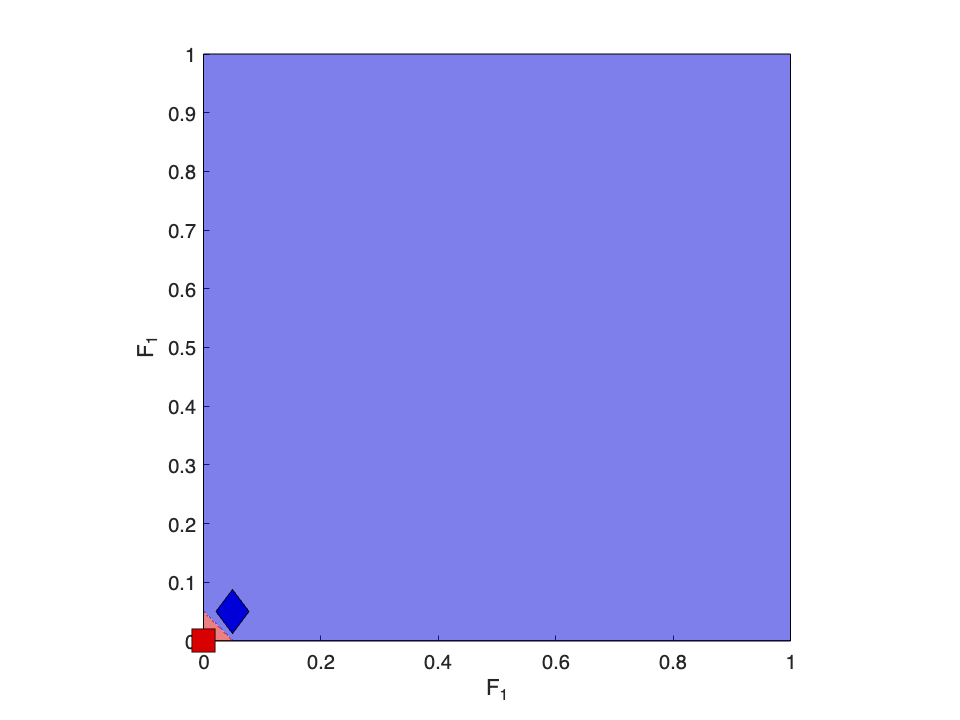

ans =     0.0013    0.9987




%Visualizing the feature space
FM_HH0.plotZones(0:0.001:1,1,[1 1],1)

savefig('FM_HH0_Zones.fig')
save('FM_HH0',"FM_HH0")
save('FM_Exp0_Results','makespans')